# Análisis de Sensibilidad e Incertidumbre de un Balancín Eólico

Amelia Hoyos Vélez y Esteban Álvarez Zuluaga

## 1. Introducción 

### 1.1 Planteamiento del problema

El aerobalancín, balancín eólico o aeropéndulo doble es un dispositivo empleado en laboratorios de control para la validación experimental de estrategias de control que posteriormente se aplican en sistemas de la industria aeroespacial y mecatrónica, como por ejemplo en vehículos autónomos no tripulados [1]. Este modelo permite estudiar una plataforma considerablemente más simple que las utilizadas en aplicaciones industriales reales, ya que posee un único grado de libertad. No obstante, conserva una estructura MISO (Multiple Input Single Output) que proporciona una dinámica suficientemente rica para el análisis y diseño de estrategias de control. Por esta razón, el estudio de este sistema constituye un ejercicio cuyos resultados pueden extrapolarse a problemas del mundo real.

En el caso del aerobalancín, el problema se formula como el modelado matemático de un péndulo cuyo pivote no se encuentra en uno de sus extremos, sino en una posición intermedia de la barra, lo que implica que uno de sus lados pueda ser más largo que el otro. En ambos extremos de la barra se disponen hélices propulsoras, controladas de manera independiente, que generan dos pares de control aplicados al sistema.

El objetivo principal es obtener una descripción analítica de la dinámica no lineal del sistema y llevar a cabo simulaciones numéricas que permitan analizar su comportamiento. A partir de este análisis, se pretende diseñar estrategias de control óptimo orientadas, por ejemplo, a la estabilización del sistema en torno a un punto de equilibrio arbitrario.

### 1.2 Modelo matemático

El modelo se deriva de sistemas similares, como el aeropéndulo con una sola hélice propulsora [2], [3]. El sistema del aerobalancín consiste en una barra rígida sujeta a un pivote en cuyos extremos están acoplados dos motores con hélices. Cada hélice genera una fuerza de empuje perpendicular a la barra, la cual induce un momento de fuerza que hace girar el sistema alrededor de su pivote, ubiccado en el origen del sistema de referencia. 

Supongamos que la fuerza de empuje $T_1$ que produce el primer motor a una distancia $l_1$ del pivote genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ producida por el segundo motor a una distancia $l_2$ del pivote genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje$y$ negativo y el eje$1$del péndulo. La masa del sistema es $m = m_b + m_1+m_2$, donde $m_b$ es la masa de la barra, $m_1$es la masa del primer motor y $m_2$ la masa del segundo motor.

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante un término lineal de rozamiento viscoso $\vec{M_4} = -c\dot{\theta}$ donde $c$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

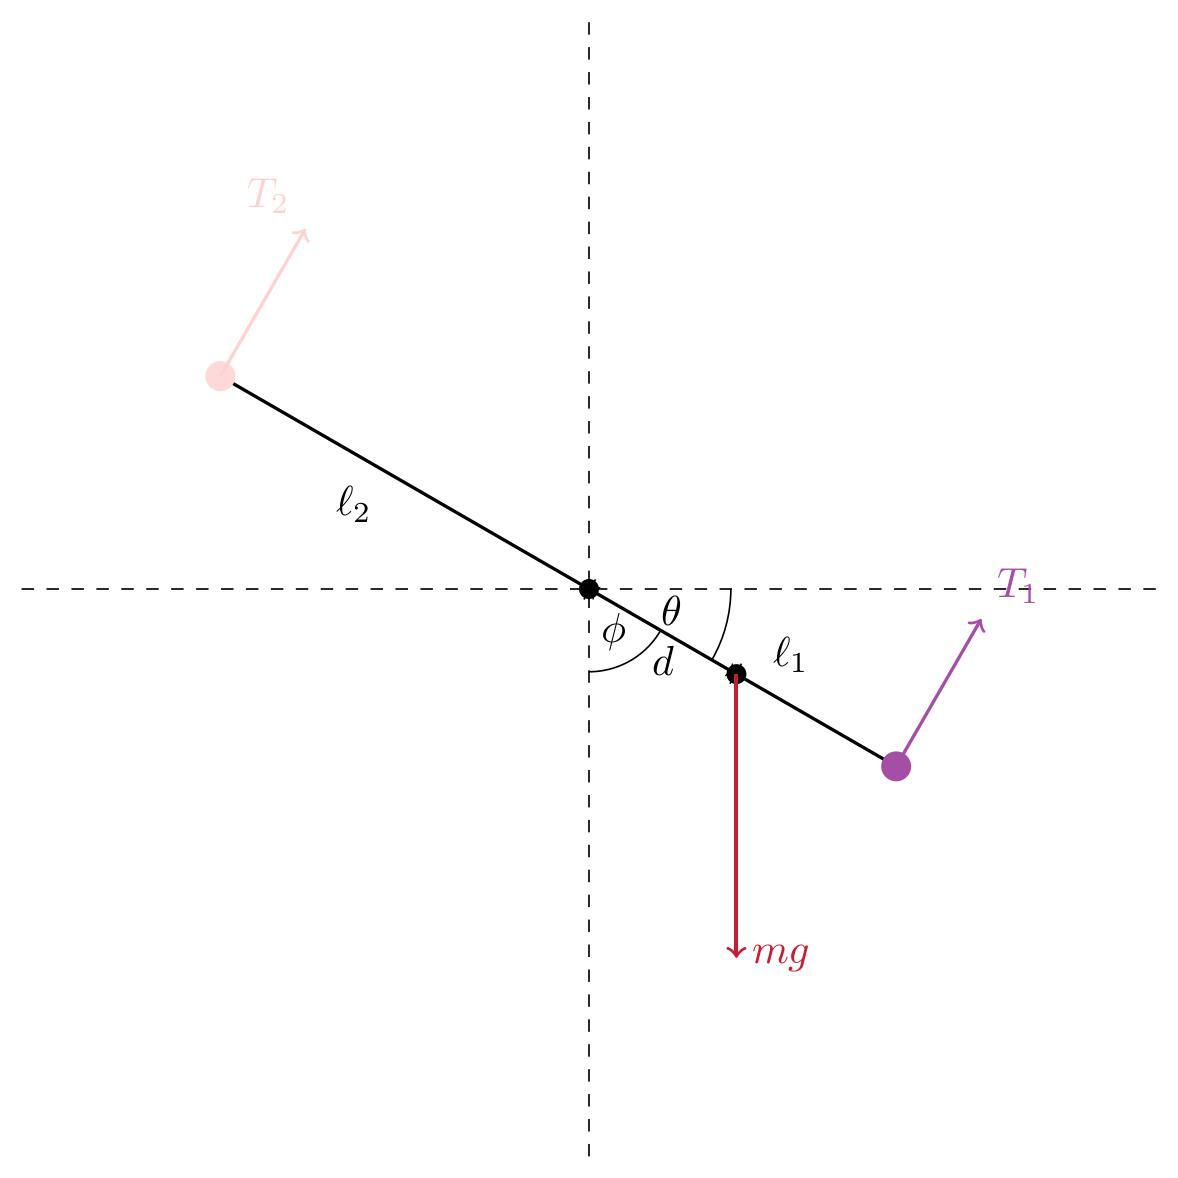

**Figura 1. Diagrama de cuerpo libre de un aerobalancín**

Según la formulación de Newton–Euler que describe la dinámica de sólidos rígidos, suponiendo un movimiento rotacional alrededor de un eje fijo de un cuerpo rígido con un momento de inercia constante y momentos respecto a dicho eje [4], la dinámica del sistema puede expresarse mediante

$\matrix{J\ddot{\theta} = \sum_{i=1}^4 M_i && (1)}$,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$\matrix{ J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - c\dot{\theta} && (2)}$.

La ecuación, debido a que $\theta = \frac{\pi}{2} - \phi$, se reescribe como

$\matrix{J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - c\dot{\theta} && (3)}
$.

En base al modelo teórico, se construye el sistema de variables de estado. Se asigna,


$$\matrix{x_1 = \theta, \qquad x_2 = \dot{\theta}, \qquad u_1 = T_1, \qquad u_2 = T_2. && (4)}


$$


Así que,


$$\matrix{\mathbf{x} = \left[\begin{array}{c} x_1 \\ x_2 \end{array}\right], \qquad \mathbf{u} = \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right]. && (5)}
$$


El sistema de variables de estado es,


$$\matrix{\left\{\begin{array}{l} \dot{x}_1 = x_2, \\ \dot{x}_2 = \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right). \end{array}\right. && (6)}
$$


En forma vectorial,


$$\matrix{\dot{\mathbf{x}} = \left[\begin{array}{c} x_2 \\ \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right) \end{array}\right]. && (7)}
$$


Así que $\dot{x} = f(\mathbf{x},\mathbf{u})$. Como puede verse, el modelo es no lineal debido al término $\frac{mgd}{J}\cos x_1$ que es de segundo orden.

### 1.3 Variables y Parámetros del Modelo

Si el punto $d$está sobre $l_1$, se define como positivo, y si está sobre $l_2$ es negativo; $d$ se calculará por defecto como


$$\matrix{d = \frac{l_1 + l_2}{2} - l_2. && (8)}
$$


El momento de inercia del aerobalancín respecto al pivote se obtiene considerando la contribución de cada uno de los elementos del sistema: la barra y los motores ubicados en sus extremos. Para trasladar los momentos de inercia al eje de rotación del sistema se emplea el teorema de ejes paralelos.

$\matrix{J = J_{\text{barra}} + J_{\text{motor}_1} + J_{\text{motor}_2} = 
\left(\frac{1}{12} m_b L^2 + m_b d^2 \right)
+ m_1 l_1^2
+ m_2 l_2^2 && (9)}
$.

El modelo del balancín eólico se formula a partir de los parámetros, vaiables de estado y entradas del sistema, los cuales se presentan en las Tablas 1, 2 y 3, respectivamente.

**Tabla 1: Parámetros del modelo**

**Tabla 2: Variables de estado del modelo**

**Tabla 3: Entradas del modelo**

### 1.4 Pregunta de Investigación

## 2. Métodos

*Implementación del modelo de simulación: *Se definen los parámetros, la función de entrada y las condiciones iniciales por defecto. Se implementa el modelo de simulación y se resuelve obteniendo las variables de estado mediante el método de Runge–Kutta.

*Definición del Régimen Nominal: *Se utiliza la librería GSUA

## 3. Resultados

### **3.1 Definición del regimen nominal de operación**

S = [];
S.description = 'Aerobalancín';
S.factor_names = 'mb m1 m2 l1 l2 g c T1 T2 theta0 theta_dot0';
S.x_nom = '[0.1 0.2 0.2 0.4 0.2 9.81 0.1 1.0 1.0 0.1 0.1]';
S.x_uncer = '20';
S.x_dist = 'L';
S.model = 'aerobalancin_ode';
S.sens_method = "Saltelli";
S.N = 50000;
S.rngN = 0;
S.scalar_characteristic = 'sum( (y-ynom).^2 )';
S.Save_to_file = '';
S = gsua_input(S);
S = gsua_sample(S);

Monte Carlo matrix generation time: 00h:00m:10s


S = gsua_methods(S); % Ejecución del análisis de sensibilidad e incertidumbre

Starting...
Percentage elapsed: 10.0%  Remaining computing time: 00h:03m:59s  Estimated stop time: 17:59:10
Percentage elapsed: 20.0%  Remaining computing time: 00h:02m:46s  Estimated stop time: 17:58:10
Percentage elapsed: 40.0%  Remaining computing time: 00h:01m:45s  Estimated stop time: 17:57:38


**Factores y su incertidumbre**

disp(S.x_table)

         `Nominal values`    `Uncertainty (%)`    `Distribution`

         `______________`    `_______________`    `____________`

    `m``        0.6314              20                L      `

    `l``        2.4466              20                L      `

    `g``        9.8106              20                L      `

    `f``        0.1277              20                L      `

**Datos del método y tiempo de cálculo**

S = gsua_sim_resume(S);
disp(S.sim_resume)

### 3.2 Análisis de Incertidumbre

Se procede a realizar el análisis de incertidumbre con simulación Montecarlo. Se realiza con un porcentaje de variación fijo, y también variable para determinar el porcentaje máximo de variación.

#### **3.2.1 Gráfico de respuesta temporal respecto a todos los factores con incertidumbre del 20%**

fignum = 1;
S.title_fontsize = 10;
S.w = 0.6;
S.h = 0.3;
S.uncer_title = ['Fig.' num2str(fignum) 'Gráfico de incertidumbre de la respuesta temporal nominal con N = ' num2str(S.N)];
gsua_plot_uncertainty(S)

#### **3.2.2 Cálculo de Porcentajes Máximos de Variación tolerables**

### 3.3 Análisis de Sensibilidad de Ajuste a la Salida Nominal

#### 3.3.1 Indices de sensibilidad de primer orden y totales

fignum = fignum + 1;
S.scalar_title = ['Fig.' num2str(fignum) 'Índices de sensibilidad escalar, N = ' num2str(S.N)];
gsua_plot_sensitivity('scalar',S)

#### **3.3.3 Análisis de incertidumbre con factor dominante fijo**

### 3.4 Análisis de sensibilidad escalar de características de la respuesta temporal 

#### **3.4.1 Valor final **

S = [];
S.description = 'Aerobalancín';
S.factor_names = 'mb m1 m2 l1 l2 g c T1 T2 theta0 theta_dot0';
S.x_nom = '[0.1 0.2 0.2 0.4 0.2 9.81 0.1 1.0 1.0 0.1 0.1]';
S.x_uncer = '20';
S.x_dist = 'L';
S.model = 'aerobalancin_ode';
S.sens_method = "Saltelli";
S.N = 20000; % Número de muestras para la simulación de Montecarlo
S.rngN = 1; % Generador de números aleatorios (con 0 se generan diferentes muestras en cada experimento)
S.scalar_characteristic = 'mean(y(end-10:end))'; % Característica escalar a ser analizada
S = gsua_input(S); % Consolidación de todos los datos necesarios para el análisis de sensibilidad e incertidumbre
S = gsua_sample(S); % Realización del muestreo de Montecarlo

S = gsua_methods(S); % Ejecución del análisis de sensibilidad e incertidumbre

fignum = fignum + 1;
S.scalar_title = ['Fig.' num2str(fignum) 'Índices de sensibilidad escalar para el valor final, N = ' num2str(S.N)];
gsua_plot_sensitivity('scalar',S)

#### **3.4.2 Tiempo de pico **

S = [];
S.description = 'Aerobalancín';
S.factor_names = 'mb m1 m2 l1 l2 g c T1 T2 theta0 theta_dot0';
S.x_nom = '[0.1 0.2 0.2 0.4 0.2 9.81 0.1 1.0 1.0 0.1 0.1]';
S.x_uncer = '20';
S.x_dist = 'L';
S.model = 'aerobalancin_ode';
S.sens_method = "Saltelli";
S.N = 20000; % Número de muestras para la simulación de Montecarlo
S.rngN = 1; % Generador de números aleatorios (con 0 se generan diferentes muestras en cada experimento)
S.scalar_characteristic = 'stepinfo(y,t).PeakTime'; % Característica escalar a ser analizada
S = gsua_input(S); % Consolidación de todos los datos necesarios para el análisis de sensibilidad e incertidumbre
S = gsua_sample(S); % Realización del muestreo de Montecarlo

S = gsua_methods(S); % Ejecución del análisis de sensibilidad e incertidumbre

fignum = fignum + 1;
S.scalar_title = ['Fig.' num2str(fignum) 'Índices de sensibilidad escalar para el tiempo de pico, N = ' num2str(S.N)];
gsua_plot_sensitivity('scalar',S)

#### **3.4.3 Sobreimpulso máximo **

S = [];
S.description = 'Aerobalancín';
S.factor_names = 'mb m1 m2 l1 l2 g c T1 T2 theta0 theta_dot0';
S.x_nom = '[0.1 0.2 0.2 0.4 0.2 9.81 0.1 1.0 1.0 0.1 0.1]';
S.x_uncer = '20';
S.x_dist = 'L';
S.model = 'aerobalancin_ode';
S.sens_method = "Saltelli";
S.N = 20000; % Número de muestras para la simulación de Montecarlo
S.rngN = 1; % Generador de números aleatorios (con 0 se generan diferentes muestras en cada experimento)
S.scalar_characteristic = 'stepinfo(y,t).Overshoot'; % Característica escalar a ser analizada
S = gsua_input(S); % Consolidación de todos los datos necesarios para el análisis de sensibilidad e incertidumbre
S = gsua_sample(S); % Realización del muestreo de Montecarlo

S = gsua_methods(S); % Ejecución del análisis de sensibilidad e incertidumbre

fignum = fignum + 1;
S.scalar_title = ['Fig.' num2str(fignum) 'Índices de sensibilidad escalar para el sobreimpulso máximo, N = ' num2str(S.N)];
gsua_plot_sensitivity('scalar',S)

#### **3.4.4 Tiempo de establecimiento**

### 3.5 Análisis de sensibilidad vectorial

fignum = fignum + 1;
S.vec_title = ['Fig.' num2str(fignum) '.Índices de sensibilidad vectorial, N = ' num2str(S.N)];
gsua_plot_sensitivity('vectorial',S)

#### **3.5.1 **Índices de sensibilidad de primer orden en el tiempo

#### **3.5.2 **Índices de sensibilidad total en el tiempo

### 4. Discusión

### 5. Bibliografía

[1] R. Breganon, U. N. L. T. Alves, J. P. L. S. De Almeida, F. S. F. Ribeiro, M. Mendonça, R. H. C. Palácios, and M. A. F. Montezuma, “Model identification and H∞ control of an aeropendulum,” *Journal of Applied Research and Technology*, vol. 21, no. 4, pp. 526–534, 2023. doi: 10.22201/icat.24486736e.2023.21.4.1741.

[2] K. Charoensuk, T. Saneewong Na Ayuthaya, P. Poungsri, L. Kirasamutranon, V. Suthiphasilp, G. Prayutte, and K. Pawananont, “The modelling and control for design aero-pendulum via proportional–integral–derivative and integral-proportional derivative,” in *Proc. 13th International Electrical Engineering Congress (iEECON)*, 2025, pp. 1–6.

[3] J. A. Alvarado Cortes, A. D. Cortes Hernandez, O. A. Domínguez Ramírez, J. D. Ramírez Zamora, J. Ortega Ventura, and L. A. Martínez Rivera, “Diseño, construcción y validación experimental de un aeropéndulo de una hélice con un grado de libertad,” *Iberociencias*, vol. 4, no. 4, pp. 1063–1092, 2025, doi: 10.63371/ic.v4.n4.a424.

[4] H. Goldstein, C. Poole, and J. Safko, *Classical Mechanics*, 3rd ed. Boston, MA, USA: Addison-Wesley, 2002.

[5] C. M. Vélez S., *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*, vol. 24. Editorial EAFIT, 2024.